% Filtro IIR Butterworth - Pasa bajo - FPGA
% filipuzzi, fernando rafael
% fecha: 20221024
% matlab2021b21b

close all; clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

**Filtro - IIR - Diseño del filtro Pasa Bajos (FPGA)**

**Parámetros de diseño**

fm=150000;             % Hz,  Frecuencia de Muestreo
fMAX=fm/2;
                         fc=1000;
fp=750 ;                  fs=6380 ;              
Ap=0.5 ;                   As=10 ;                          

**Diseño del filtro**

- Transformar las caracteristicas de frecuencia de paso bajo a paso bajo normalizado

Fc=fc/fc;
Fs=fs/fc;
Fp=fp/fc;

- Orden del filtro:

N=mi_butter_orden_lp(Fp, Ap, Fs, As)

N =      4


- Función de transferencia y respuesta en frecuencia

[BS, AS]=mi_butter(N);
sysS=tf(BS,AS)

sysS =
 
                   
                  1
                   
  ---------------------------------
                                   
  s^4 + 2.613 s^3 + 3.414 s^2      
                                   
                      + 2.613 s + 1
                                   
 
Continuous-time transfer function.



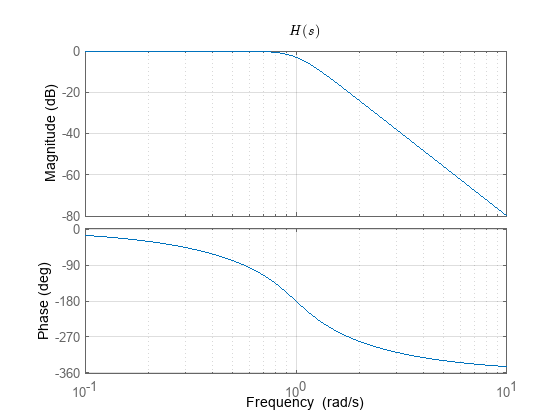

fig0=figure; bode(sysS); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;...
saveas(fig0,'output/fpga_iir_lp_butterworth_0','jpg');

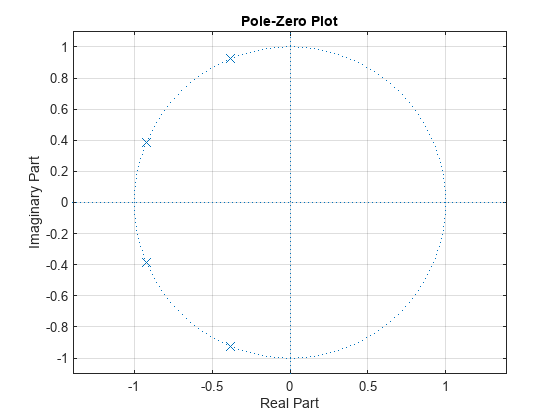


fig1=figure; Np=max(length(BS),length(AS));
zplane( [zeros(1, Np-length(BS)) BS], [  zeros(1, Np-length(AS)) AS] );...
grid on; saveas(fig1,'output/fpga_iir_lp_butterworth_1','jpg');


syms s; ecu_latex = ['H(s)=', latex(poly2sym(BS,s)/poly2sym(AS,s))];
save_ecu('output/fpga_iir_lp_butterworth_ecu_SM.tex', ecu_latex);

- Transformación en frecuencia

[Bs, As] = mi_lp2lp(BS, AS, 2*pi*fc);
syss=tf(Bs,As)

syss =
 
                      
              4.284e27
                      
  ---------------------------------
                                   
  2.749e12 s^4 + 4.513e16 s^3      
                                   
          + 3.705e20 s^2           
                                   
            + 1.782e24 s + 4.284e27
                                   
 
Continuous-time transfer function.



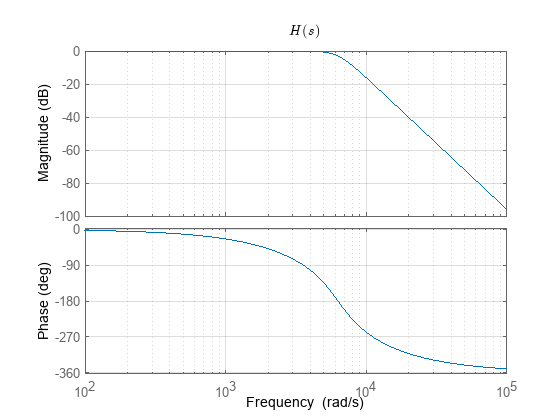

fig2=figure; bode(syss); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;   ...
saveas(fig2,'output/fpga_iir_lp_butterworth_2','jpg');

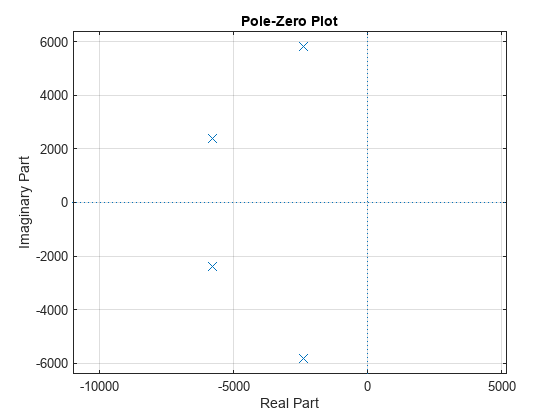


fig3=figure; Np=max(length(Bs),length(As));
zplane( [zeros(1, Np- length(Bs)) Bs  ], [zeros(1, Np- length(As))  As ] ); ...
grid on; saveas(fig3,'output/fpga_iir_lp_butterworth_3','jpg');

syms s; ecu_latex = ['H(s)=', latex(poly2sym(Bs,s)/poly2sym(As,s))];
save_ecu('output/fpga_iir_lp_butterworth_ecu_s.tex', ecu_latex);

**Transformación bilinear - matlab.**

mapeo="bilineal(matlab)";

switch mapeo
    case "integración"
        [Bz, Az]=mi_integral(Bs, As, fm);
    case "invariante al impulso"
        [Bz, Az]=mi_impinvar(Bs, As, fm);
    case "invariante(matlab)"
        [Bz, Az]=impinvar(Bs, As, fm);
    case "bilineal"
        [Bz, Az]=mi_bilinear(Bs, As, fm, fs);
    case "bilineal(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm);     
    case "bilineal-prewarping(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm, fc); 
end

m=max( abs([ Bz, Az ]) ); Bz=Bz/m; Az=Az/m;
Bz=Bz/Az(1); Az=Az/Az(1);
sysz=tf(Bz,Az,1/fm,'Variable','z^-1')

sysz =
 
                                   
  1.822e-07 + 7.287e-07 z^-1       
                                   
          + 1.093e-06 z^-2         
                                   
          + 7.287e-07 z^-3         
                                   
                   + 1.822e-07 z^-4
                                   
  ----------------------------------
                                    
  1 - 3.891 z^-1 + 5.678 z^-2       
                                    
          - 3.683 z^-3 + 0.8963 z^-4
                                    
                                    
 
Sample time: 6.6667e-06 seconds
Discrete-time transfer function.



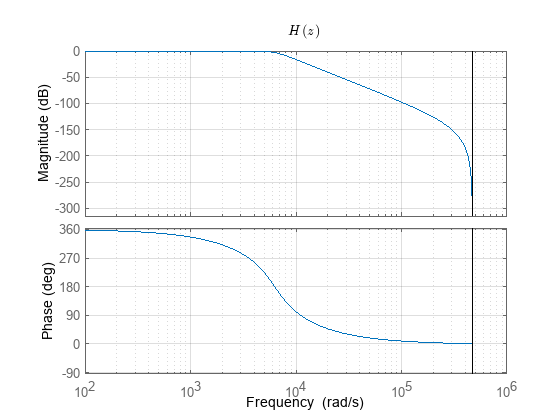

syms z; fig4=figure; bode(sysz); grid on;...
title(sprintf('$$%s$$', 'H(z)'), 'Interpreter','latex');    ...
saveas(fig4, 'output/fpga_iir_lp_butterworth_4', 'jpg');

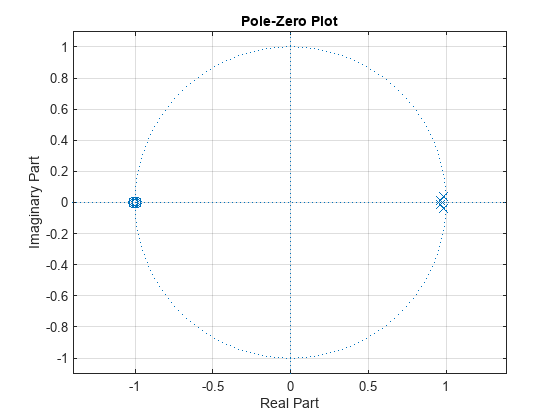


fig5=figure; Np=max( length(Bz),length(Az) );
zplane( [  zeros(1, Np- length(Bz)) Bz], [ zeros(1, Np- length(Az)) Az ] );...
grid on; saveas(fig5,'output/fpga_iir_lp_butterworth_5','jpg');

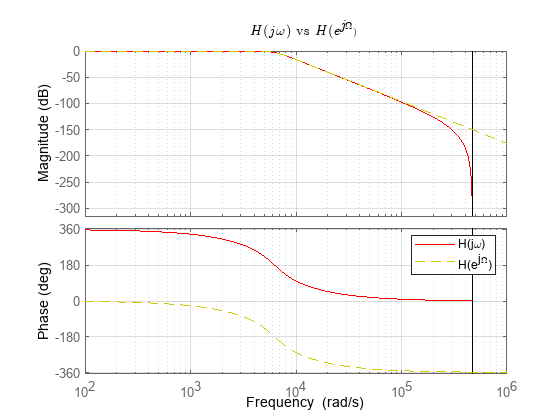


fig6=figure; bode(sysz,'r',syss,'y--'); grid on;...
title(sprintf('$$%s$$', 'H(j\omega)\mbox{ vs }H(e^{j\Omega})'), 'Interpreter','latex');    ...    
legend( sprintf('%s', 'H(j\omega)'), sprintf('%s', 'H(e^{j\Omega})'));    
saveas(fig6,'output/fpga_iir_lp_butterworth_6','jpg');

syms z; ecu_latex = ['H(z)=', latex(poly2sym(Bz,z)/poly2sym(Az,z))];
save_ecu('output/fpga_iir_lp_butterworth_ecu_z.tex', ecu_latex);

**Generación de la linea para la fpga**

Nbits=64;
Qbits=32;
fpga_coef=to_fpga(Bz, Az, N, fm, Qbits,Nbits, 'IIR - Pasa Bajo', mapeo)

fpga_coef =     '//Filtro IIR - Pasa Bajo - bilineal(matlab)
     //Orden: 4
     //Frecuencia de Muestreo: 150000 (Hz)
     assign dx0=64'0x000000000000030F;assign dx1=64'0x0000000000000C3A;assign dx2=64'0x0000000000001257;assign dx3=64'0x0000000000000C3A; 
     			assign dx4=64'0x000000000000030F;
     assign dy1=64'0x00000003E3FBA9CA;assign dy2=64'0xFFFFFFFA5287249A;assign dy3=64'0x00000003AEF26CCD; 
     			assign dy4=64'0xFFFFFFFF1A8A93EA;'


saveImplementacion('output/fpga_iir_lp_butterworth_fpga_coef.txt', fpga_coef); ...
fprintf('%s\n',fpga_coef) 

//Filtro IIR - Pasa Bajo - bilineal(matlab)
//Orden: 4
//Frecuencia de Muestreo: 150000 (Hz)
assign dx0=64'0x000000000000030F;assign dx1=64'0x0000000000000C3A;assign dx2=64'0x0000000000001257;assign dx3=64'0x0000000000000C3A; 
			assign dx4=64'0x000000000000030F;
assign dy1=64'0x00000003E3FBA9CA;assign dy2=64'0xFFFFFFFA5287249A;assign dy3=64'0x00000003AEF26CCD; 
			assign dy4=64'0xFFFFFFFF1A8A93EA;


**Generación de la linea para inicializar el callback de simulink**

PRECISION_SIMULINK=8;
simulink_coef=to_simulink(Bz, Az, N, fm, PRECISION_SIMULINK, 'IIR - Butterworth - Pasa Bajo', mapeo); ...
saveImplementacion('output/stm32_iir_lp_butterworth_simulink_coef.txt', simulink_coef); ...
fprintf('%s\n', simulink_coef) 

	%Filtro IIR - Butterworth - Pasa Bajo - bilineal(matlab) 
	%Orden: 4
	%Frecuencia de Muestreo: 150000 (Hz)
	Fm=150000;
	ORDEN=4;
	coef_x= [1.8216448e-07,7.2865793e-07,1.0929869e-06,7.2865793e-07,1.8216448e-07 ...
			];
	coef_y= [-1,3.8905588,-5.6776254,3.6833866,-0.89632297 ...
			];


save('output/fpga_iir_lp_butterworth.mat');